Edgar Perez Blanco

clear all
format shortG

x = (1:7)';
y = [45.27 47.73 52.09 53.29 54.56 54.92 55.46]'; % Aceite de soja

% Polinomios interpoladores
recta = polyfit(x,y,1);
parabola = polyfit(x,y,2);
cubica = polyfit(x,y,3);
P = polyfit(x,y,6);

% Valores predecidos
predict_recta = polyval(recta,x);
predict_parabola = polyval(parabola,x);
predict_cubica = polyval(cubica,x);
predict_P = polyval(P,x);

% Residuos
residuo_recta = abs(y - predict_recta);
residuo_parabola = abs(y - predict_parabola);
residuo_cubica = abs(y - predict_cubica);
residuo_P = abs(y - predict_P);

RES = [x y predict_recta residuo_recta predict_parabola residuo_parabola predict_cubica residuo_cubica predict_P residuo_P];
T1 = array2table(RES, "VariableNames", {'x' 'y' 'predict_recta' 'residuo_recta' 'predict_parabola' 'residuo_parabola' 'predict_cubica' 'residuo_cubica' 'predict_P' 'residuo_P'})

T1 = 7×10 table
    x      y      predict_recta    residuo_recta    predict_parabola    residuo_parabola    predict_cubica    residuo_cubica    predict_P    residuo_P 
    _    _____    _____________    _____________    ________________    ________________    ______________    ______________    _________    __________

    1    45.27       46.822            1.5521            45.069              0.20143             44.98            0.28976         45.27      2.7711e-13
    2    47.73       48.516           0.78571            48.516              0.78571            48.604            0.87405         47.73      1.7764e-13
    3    52.09       50.209        

% Prediccion de 20/21 -> abcisa 8
predict_2021_recta = polyval(recta,8);
predict_2021_parabola = polyval(parabola,8);
predict_2021_cubica = polyval(cubica,8);
predict_2021_P = polyval(P,8);

predict_2021 = [predict_2021_recta; predict_2021_parabola; predict_2021_cubica; predict_2021_P]

predict_2021 =        58.677
       54.469
       54.999
         84.4


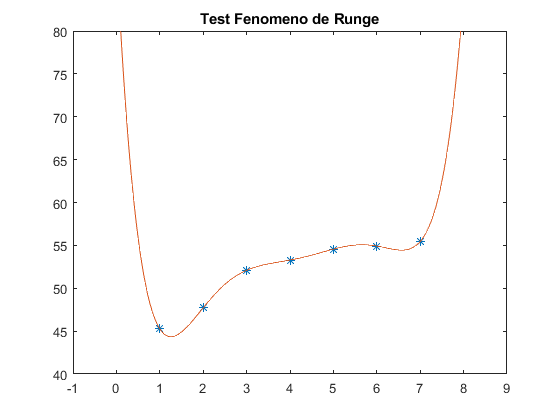


test_x = linspace(-1,9,500);
% Runge
plot(x,y,'*',test_x,polyval(P,test_x),'-'); xlim([-1 9]); ylim([40 80]); title("Test Fenomeno de Runge");

Aparentemente no vemos el fenomeno de Runge **entre las muestras**, ya que no se ven picos pronunciados entre diferentes muestras. Se ve sin apenas oscilaciones, y persolamente parece una interpolacion buena.** El problema vendra a la hora de exprolar en la abcisa 8, donde si que podemos ver como crece de forma fortisima y es un valor que podriamos considerar real o bueno, **por lo tanto debemos considerarlo invalido para extrapolaciones ya que no represental la realidad.

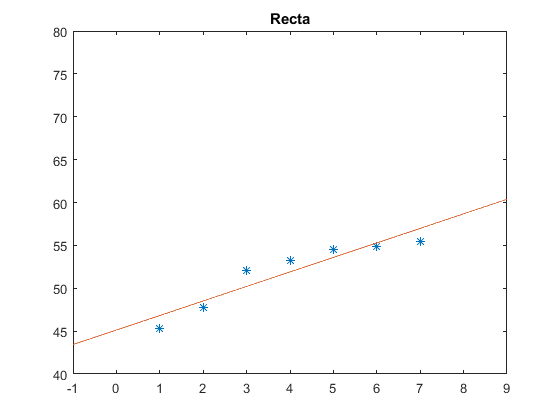

% Recta
plot(x,y,'*',test_x,polyval(recta,test_x),'-'); xlim([-1 9]); ylim([40 80]); title("Recta");

Considero la recta un modelo poco preciso, ya que los residuos no son pequenos, pero sin embargo es realista, en el sentido de que mantiene la tendencia de crecimiento y refleja que ademas este, con estas muestras, parece ser lineal. Por lo tanto, para predecir de forma precisa que pasara el ano que viene, probablemente no sea la mejor opcion, pero se acercara lo suficiente.

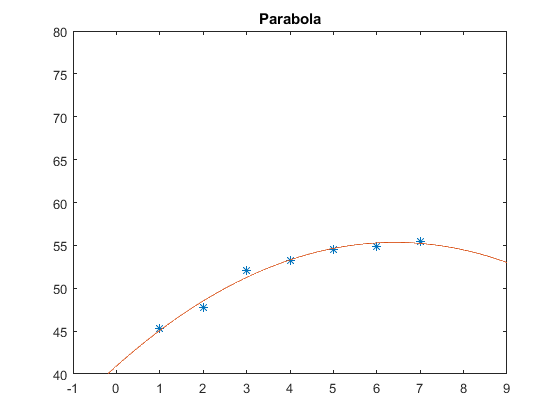

% Parabola
plot(x,y,'*',test_x,polyval(parabola,test_x),'-'); xlim([-1 9]); ylim([40 80]); title("Parabola");

El ajuste por parabola no me parece correcto porque a pesar de que no cuenta con grandes desviaciones, refleja que los siquientes anos los valores van a descender, cuando deberiamos sacar como conclusion que la tendencia es de creciemiento (el mismo enunciado lo dice). Por lo tanto se ajusta bastante bien a los valores dados, pero no sera bueno para predecir valores futuros.

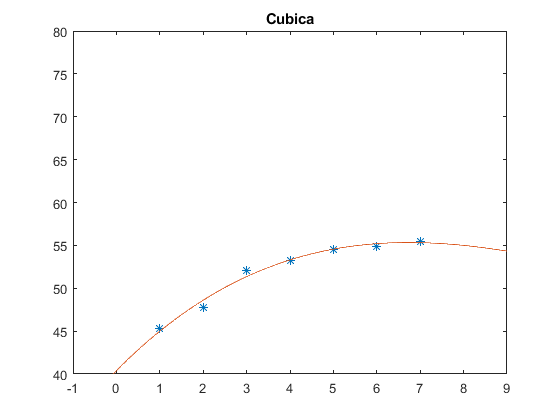

% Cubica
plot(x,y,'*',test_x,polyval(cubica,test_x),'-'); xlim([-1 9]); ylim([40 80]); title("Cubica");

El ajuste de la curva cubica, igual que le sucede a la parabola, refleja un decrecimiento en las proximas muestras, lo cual no parece conveniente. Aun asi, la magnitud de los residuos es bastante semejante al de la parabola. No es una buena opcion para predecir valores futuros.

#### CONCLUSION

Por lo tanto, para estudiar el crecimiento y que expectativas tener sobre futuros valores sobre el consumo, me quedaria por la recta por ser creciente, o como mucho, asumiendo que el consumo se puede reducir, la parabola o la cubica. Sin embargo no escogeria los valores del polinomio interpolador porque como hemos visto, al extrapolar con abcisa = 8, el valor se dispara de forma irreal. 

%% Tabla de errores
ERR = [x y residuo_recta residuo_parabola residuo_cubica residuo_P];
T1 = array2table(ERR, "VariableNames", {'x' 'y' 'error_recta'  'error_parabola'  'error_cubica' 'error_P'})

T1 = 7×6 table
    x      y      error_recta    error_parabola    error_cubica     error_P  
    _    _____    ___________    ______________    ____________    __________

    1    45.27       1.5521          0.20143          0.28976      2.7711e-13
    2    47.73      0.78571          0.78571          0.87405      1.7764e-13
    3    52.09       1.8807          0.82857          0.74024      4.4054e-13
    4    53.29       1.3871         0.015714         0.015714      9.2371e-14
    5    54.56      0.96357         0.088571        0.0002381      2.9843e-13
    6    54.92         0.37             0.37          0.28167      1.4211e-12
    7    55.46       1.5236             0.23          0.14167      2.8066e-12
